### **Digital Communication CA1 **

**golmehr khosrokhavr - student ID : 810198507**

#### Q12

 -- generating symbols 

presenet_state = 1; 
    vector_of_symbols= zeros(1, 10000);
for i = 1: 10000
    random_number = rand(1);
    
    if (presenet_state == 1)&(random_number >= 0.5)   %% stays in state 1; B 
           presenet_state = 1; 
           vector_of_symbols(i) = 1; 
     
    elseif(presenet_state == 1)&(random_number < 0.5)  %%goes to state 2; A
           presenet_state = 2; 
           vector_of_symbols(i) = 0;
      
    elseif(presenet_state == 2)&(random_number < 0.2)  %%STAYS to state 2; B
           presenet_state = 2; 
           vector_of_symbols(i) = 1;
    
    elseif(presenet_state == 2)&(random_number >= 0.2)  %%goes to state 1; A 
           presenet_state = 1; 
           vector_of_symbols(i) = 0; 
    end
    
end

Calculationg and Plotting average length - Entropy and Code efficency 

transition_matrix = [0.5 0.5; 0.8 0.2];
H = entropy(transition_matrix, 1000000)

H = 0.8371

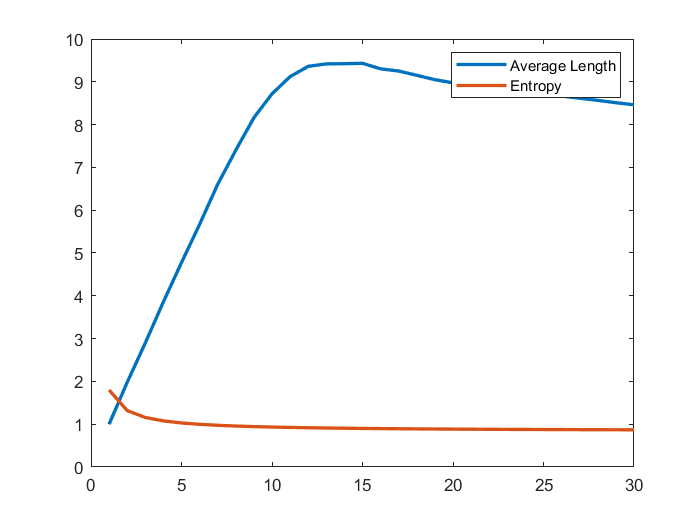

%H2 = entropy2(transition_matrix,1000000)
AVGs = zeros (1,10);
Gs = zeros (1,10);
Code_Eff = zeros (1,10);

for i = 1 : 30
AVGs(i) = average_length_of_huffman_code(vector_of_symbols,i);
Gs(i) = entropy(transition_matrix,i);
Code_Eff(i) = i* H./AVGs(i);
end 

plot (1:30, AVGs,'LineWidth',2);
hold on
plot (1:30, Gs,'LineWidth',2);
%plot (1:30,Code_Eff,'LineWidth',2);
legend('Average Length','Entropy');
hold off

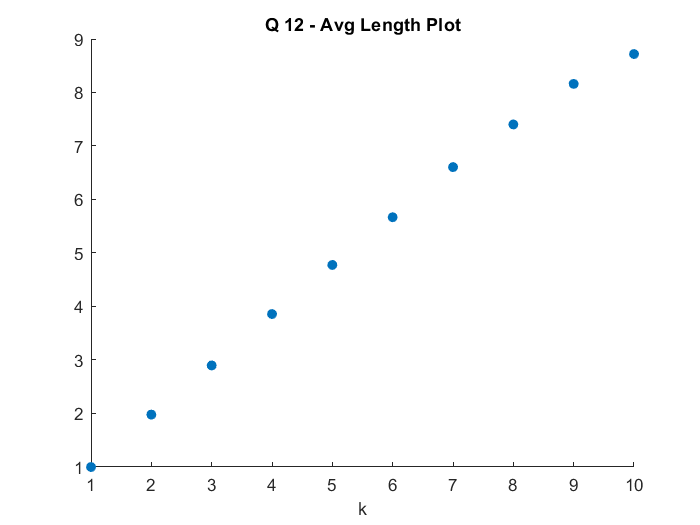

scatter(1:10,AVGs,'filled')
title('Q 12 - Avg Length Plot')
xlabel('k')

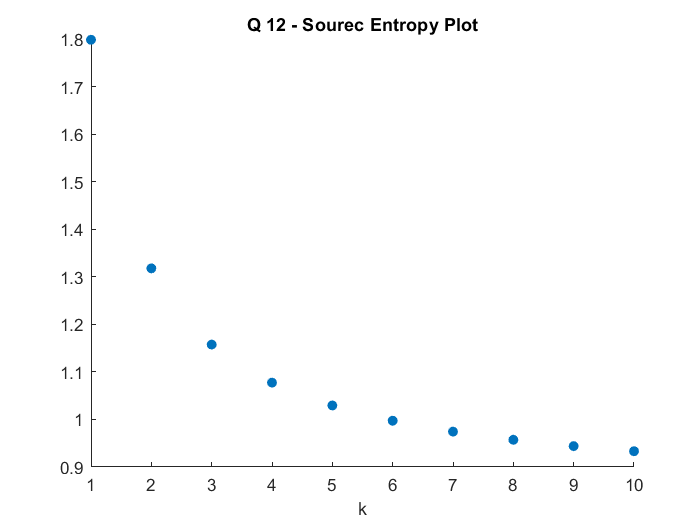


scatter(1:10,Gs,'filled')
title('Q 12 - Sourec Entropy Plot')
xlabel('k')

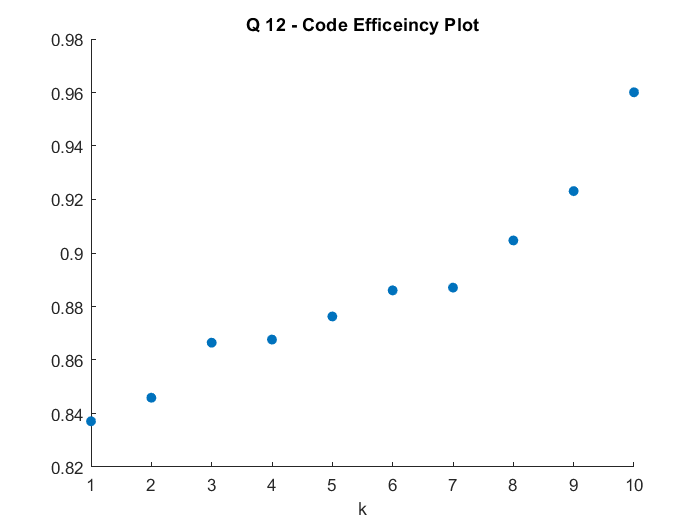


scatter(1:10,Code_Eff,'filled')
title('Q 12 - Code Efficeincy Plot')
xlabel('k')

#### Q 13

 -- generating symbols 

Source 1 

transition_matrix2 = [0.01 0.29 0.7; 0.01 0.29 0.7; 0.01 0.29 0.7];
a1= 1:3;
vector_of_symbols_Src1 =randsrc(10000, 1, [a1;p1]); 
AVGs1 = zeros (1,10);
Gs1 = zeros (1,10);
Code_Eff1 = zeros (1,10);
p1 = [ 0.01,0.7 , 0.29];

H_Src1 = 0; 
for i = 1: 3
    H_Src1 = H_Src1 - p1(i).* log2 (p1(i));
end
H_Src1

H_Src1 = 0.9445

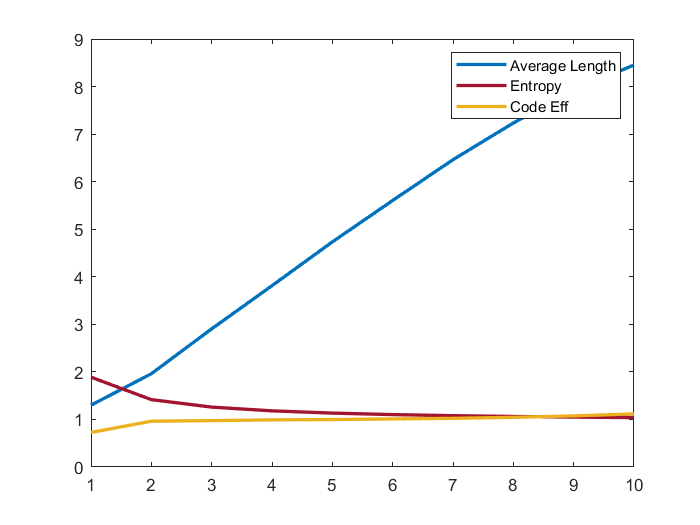


for i = 1 : 10
AVGs1(i) = average_length_of_huffman_code(vector_of_symbols_Src1,i);
Gs1(i)= ((i+1)./i).*H_Src1;
Code_Eff1(i) = i*H_Src1./AVGs1(i);
end 

plot (1:10, AVGs1,'LineWidth',2);
hold on
plot (1:10, Gs1,'LineWidth',2,'color',[0.6350 0.0780 0.1840]);

plot (1:10,Code_Eff1,'LineWidth',2);
legend('Average Length','Entropy', 'Code Eff');
hold off

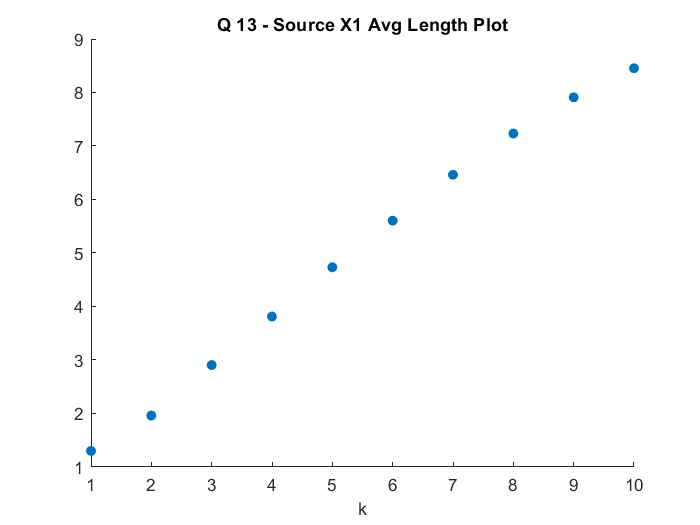


scatter(1:10,AVGs1,'filled')
title('Q 13 - Source X1 Avg Length Plot')
xlabel('k')

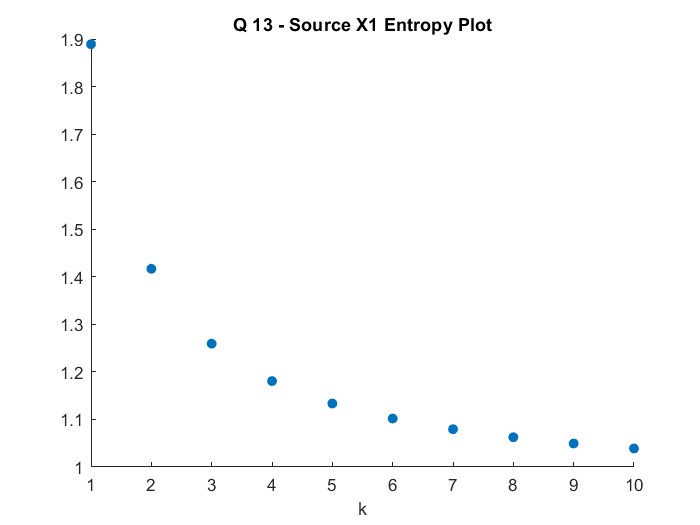


scatter(1:10,Gs1,'filled')
title('Q 13 - Source X1 Entropy Plot')
xlabel('k')

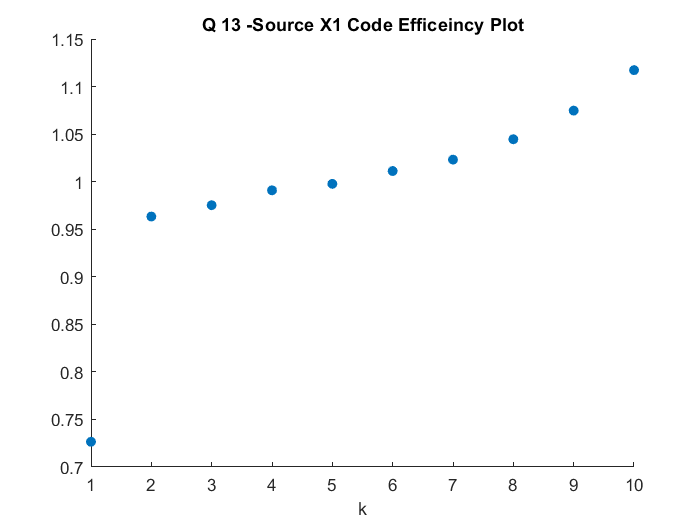


scatter(1:10,Code_Eff1,'filled')
title('Q 13 -Source X1 Code Efficeincy Plot')
xlabel('k')

Source 2 

a2 = 1:9;
p2 = kron(p1,p1);
vector_of_symbols_Src2 =randsrc(10000, 1, [a2;p2]); 
transition_matrix_Src2 = kron(transition_matrix2,transition_matrix2);

AVGs2 = zeros (1,10);
Gs2 = zeros (1,10);
Code_Eff2 = zeros (1,10);

H_Src2 = 0;
H_Src2 = sum(p2.* log2 (p2));
H_Src2 = -H_Src2

H_Src2 = 1.8891

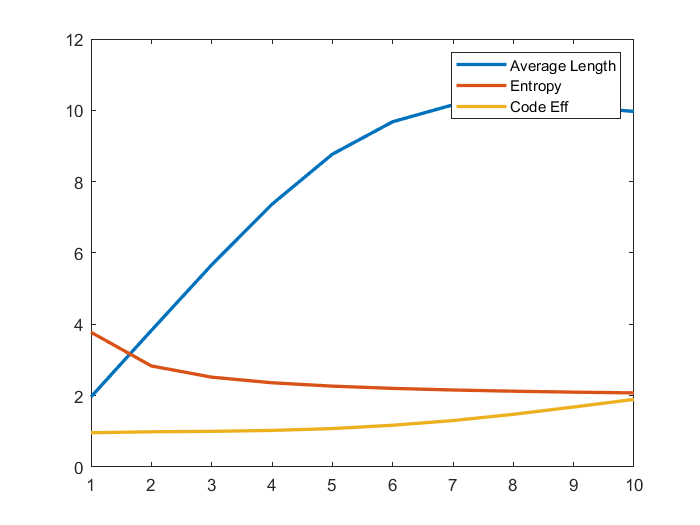


for i = 1 : 10
AVGs2(i) = average_length_of_huffman_code(vector_of_symbols_Src2,i);
Gs2(i) =((i+1)/i).*H_Src2;
Code_Eff2(i) =i .*H_Src2./AVGs2(i);
end 

plot (1:10, AVGs2,'LineWidth',2);
hold on
plot (1:10, Gs2,'LineWidth',2);
plot (1:10,Code_Eff2,'LineWidth',2);
legend('Average Length','Entropy', 'Code Eff');
hold off

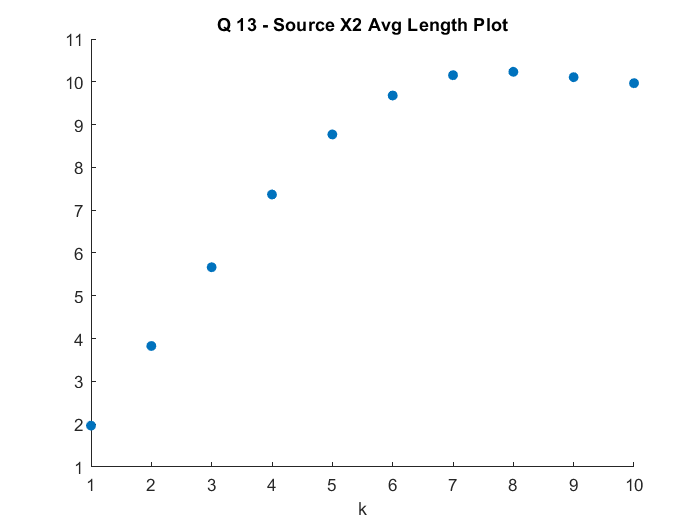


scatter(1:10,AVGs2,'filled')
title('Q 13 - Source X2 Avg Length Plot')
xlabel('k')

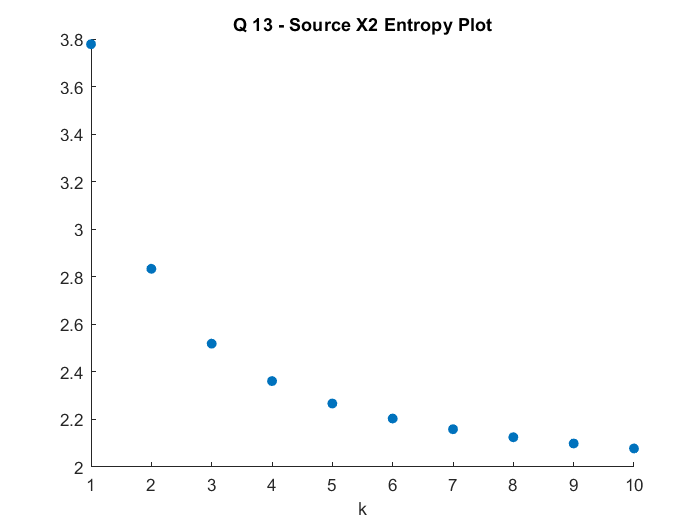


scatter(1:10,Gs2,'filled')
title('Q 13 - Source X2 Entropy Plot')
xlabel('k')

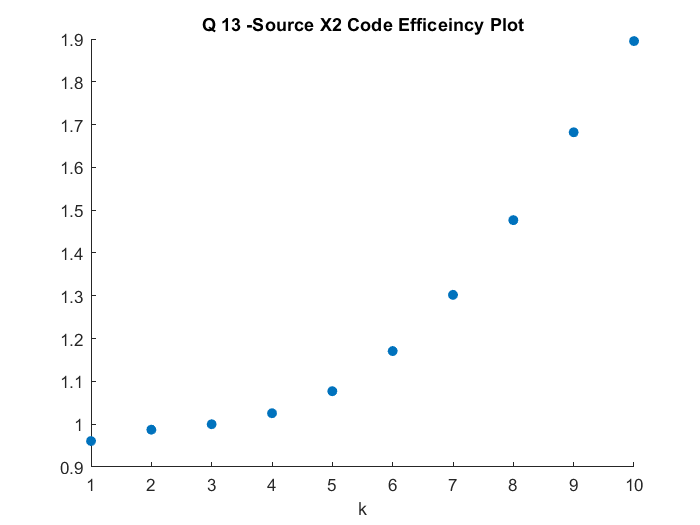


scatter(1:10,Code_Eff2,'filled')
title('Q 13 -Source X2 Code Efficeincy Plot')
xlabel('k')

Source 3 

a3 = 1:27;
p3 = kron(p2,p1);
vector_of_symbols3 =randsrc(10000, 1, [a3;p3]); 
transition_matrix_Src3 = kron(transition_matrix_Src2,transition_matrix2);

AVGs3 = zeros (1,10);
Gs3 = zeros (1,10);
Code_Eff3 = zeros (1,10);

H_Src3 = 0;
H_Src3 = sum(p3.* log2 (p3));
H_Src3 = -H_Src3

H_Src3 = 2.8336

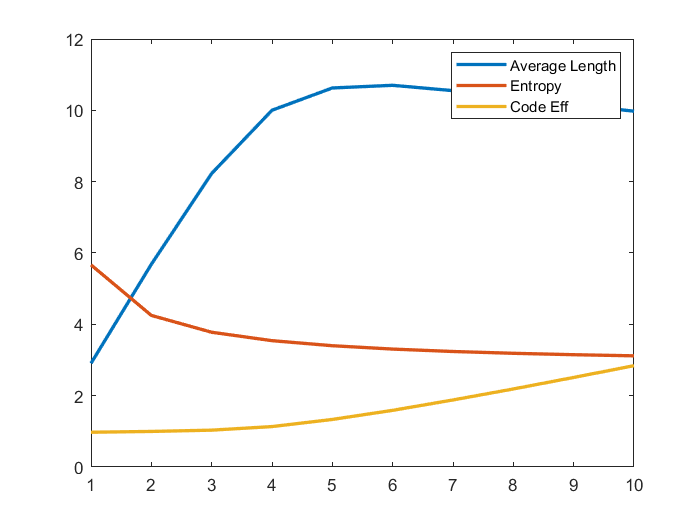


for i = 1 : 10
AVGs3(i) = average_length_of_huffman_code(vector_of_symbols3,i);
Gs3(i) =((i+1)/i).*H_Src3;
Code_Eff3(i) =i.* H_Src3./AVGs3(i);
end 

plot (1:10, AVGs3,'LineWidth',2);
hold on
plot (1:10, Gs3,'LineWidth',2);
plot (1:10,Code_Eff3,'LineWidth',2);
legend('Average Length','Entropy', 'Code Eff');
hold off

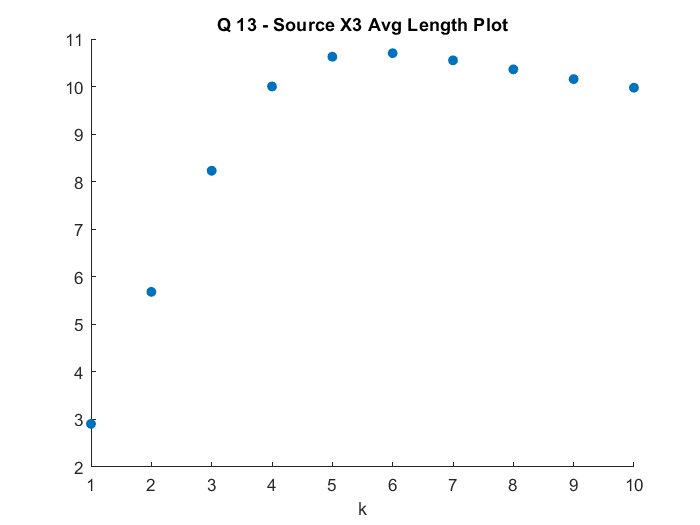



scatter(1:10,AVGs3,'filled')
title('Q 13 - Source X3 Avg Length Plot')
xlabel('k')

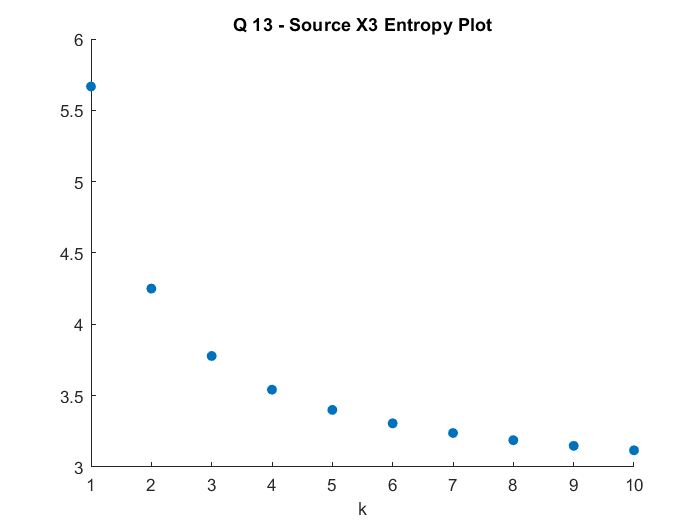


scatter(1:10,Gs3,'filled')
title('Q 13 - Source X3 Entropy Plot')
xlabel('k')

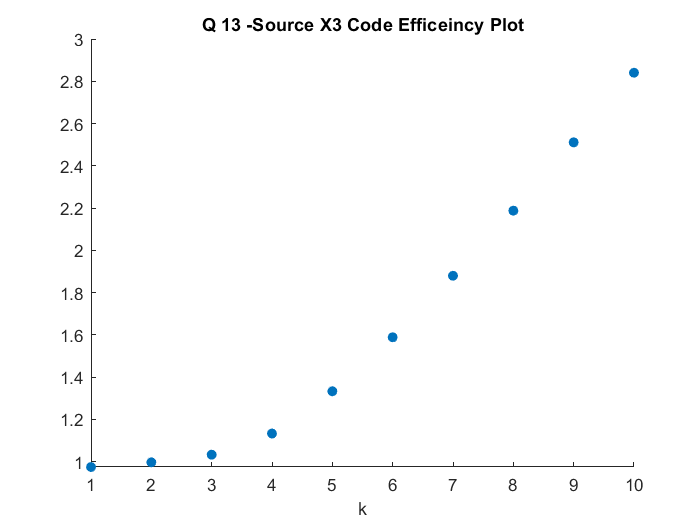


scatter(1:10,Code_Eff3,'filled')
title('Q 13 -Source X3 Code Efficeincy Plot')
xlabel('k')

H_Src1

H_Src1 = 0.9445

H_Src2

H_Src2 = 1.8891

H_Src3

H_Src3 = 2.8336

function G_k = entropy (transition_matrix , k)
    [V,D] = eig(transition_matrix');
    P = V(:,1)';
    P = P./sum(P);
    [n,m] = size(transition_matrix); 
       
    H_0 = sum (P.*log2(P));
    H_0 = -H_0;
    H_1 = 0 ; 
    temp_h = sum(transition_matrix.*log2(transition_matrix));
    H_1 = sum(P.*temp_h);
    H_1 = -H_1;
    G_k= (H_0 + k.*H_1)./k;   
end



function G_k = entropy2 (transition_matrix , k)
    [V,D] = eig(transition_matrix');
    P = V(:,1)';
    P = P./sum(P);
    [n,m] = size(transition_matrix); 
       
    H_0 = 0;
    for i = 1: n
        H_0 = H_0 - P(i).* log2 (P(i));
    end
    
    H_1 =0;
    for i = 1:n 
        temp_h = 0;
        for j = 1: m
            temp_h =temp_h + transition_matrix(i,j).*log2(transition_matrix(i,j));
        end
        H_1 = H_1 - P(i).*temp_h;
    end

    G_k= (H_0 + k.*H_1)./k;   
end

function AVG_length = average_length_of_huffman_code(chain , k)
    n = floor( length(chain)/k); 

    chain_new = chain (1:n.*k);
    k_symbols = reshape(chain_new,[k,n]);
    k_symbols = k_symbols';
    [unique_symbols, ia,ic] = unique(k_symbols, 'rows', 'stable');
    tedad = accumarray (ic,1); 
    prob = tedad/ n;
    
    [dict, AVG_length] = huffmandict(1:length(prob), prob);
end
